clear clc
syms vin vout s c r w H a denHreal denH numH positive

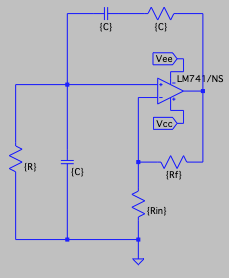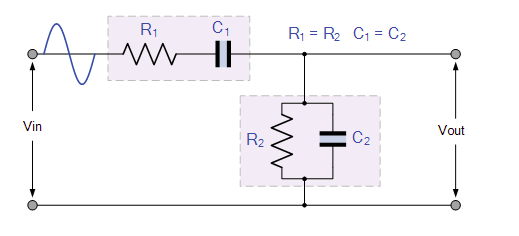

Como esse é um circuito mais simples é poossivel encontrar a relação Vout/Vin a partir de um divisor de tensão. Para tal é preciso antes simplificar R e C que estão em paralelo. 

Em seguida, se usa a formula levando em consideracao que a tensao total é Vin e a parcial Vout

paralRC = paraleloSym(r, 1/(s*c));
eq = vin*paralRC/(paralRC + r + 1/(s*c)) - vout == 0

$$eq = \frac{\mathrm{vin}}{\left(c\,s+\frac{1}{r}\right)\,\left(r+\frac{1}{c\,s+\frac{1}{r}}+\frac{1}{c\,s}\right)}-\mathrm{vout}=0$$

Isolando vin/vout para obter H

H = solve(eq, vout) / vin

$$H = \frac{c\,r\,s}{c^{2}\,r^{2}\,s^{2}+3\,c\,r\,s+1}$$

Feito isso precisamos isolar a parte real do denominador

[numH, denH] = numden(H);

Fazendo s=jw

s = 1i*w;
H = subs(H)

$$H = \frac{c\,r\,w\,\mathrm{i}}{-c^{2}\,r^{2}\,w^{2}+3\,c\,r\,w\,\mathrm{i}+1}$$

denH = subs(denH);
denHreal = subs(denH, 1i, 0);

$$denHreal = 1-c^{2}\,r^{2}\,w^{2}$$

Igualando a zero e extraindo W temos

denHreal = denHreal == 0

$$denHreal = 1-c^{2}\,r^{2}\,w^{2}=0$$

  w = solve(denHreal, w);
  w = simplify(w) 

$$w = \frac{1}{c\,r}$$

Agora, para demonstrar o ganho substituimos a frequencia encontrada na equacao. Dessa forma:

A = subs(H)

$$A = \frac{1}{3}$$